% clear;clc;

- run this script first to set the right path

addpath(genpath('/Users/lyys/MyDocs/repos_from_github/gkaModelEye'))

poses={[-10,-10,0,2],[-5,-5,0,2],[5,5,0,2],[10,10,0,2],[-10,10,0,2],[-5,5,0,2],[5,-5,0,2],[10,-10,0,2]};
colors={'r','b','c','g','r','b','c','g'};

num_lights=2;
light_positions=[-10,0,0;10,0,0]';
% light_positions=[0,0,0]';
sg=createSceneGeometry('cameraGlintSourceRelative',light_positions);


output={}


output =

  0×0 empty cell array



for i=1:size(poses,2)
    glint_1st=[];
    glint_4th=[];
    [~,glint_coord_lyy,~,~,~,~,point_labels_lyy,~,~,glint_initial_ray]=projectModelEye_lyy(poses{i},sg,'fullEyeModelFlag',false);
    
    for j=1:num_lights
        glint_1st(j,:)=glint_coord_lyy(j,:);
        glint_4th(j,:)=glint_coord_lyy(j+num_lights,:);
    end
    output{i}={glint_1st,glint_4th};
    
end

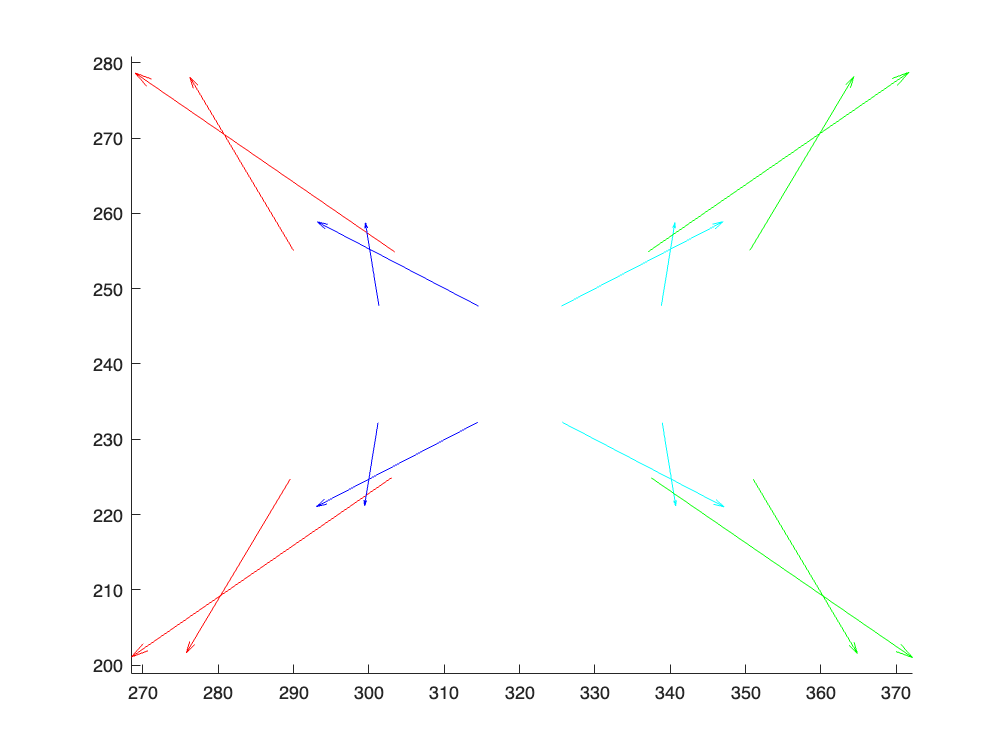

  -15.3042   25.6077
  -38.3322   26.4151

   -1.9916   12.2485
  -23.7997   12.4376

   23.8687  -12.4617
    1.9911  -12.2716

   38.5536  -26.5219
   15.3750  -25.7069

  -15.3335  -25.6454
  -38.4064  -26.4555

   -1.9934  -12.2572
  -23.8220  -12.4467

   23.8463   12.4526
    1.9893   12.2629

   38.4790   26.4813
   15.3456   25.6691



figure
axis equal
% xlim([0 640]);
% ylim([0 480]);
hold on
for i=1:size(poses,2)
    glints_1st_tmp=output{i}{1};
    glints_4th_tmp=output{i}{2};
    vectors=glints_4th_tmp-glints_1st_tmp;
    disp(vectors)
    % scatter(glints_1st_tmp(:,1),glints_1st_tmp(:,2),'r')
    % scatter(glints_4th_tmp(:,1),glints_4th_tmp(:,2),'b')
    for j=1:num_lights
        quiver(glints_1st_tmp(j,1),glints_1st_tmp(j,2),vectors(j,1),vectors(j,2),colors{i})
    end
end

glint_initial_ray

glint_initial_ray =   120.0000   10.0000         0
   -0.9974   -0.0713   -0.0058


pupilEllipseParams = 1.0e+03 *

    0.2390    0.2400    6.7311    0.0004    0.0016


imagePoints =   252.7128  199.1814
  223.6279  204.7441
  206.6328  230.8137
  211.4851  262.1948
  235.4107  280.7188
  264.5930  275.4608
  281.8699  249.2846
  276.9201  217.5988
  244.0511  240.0000
  244.0511  240.0000


pointLabels = 639×1 cell array
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopCenter'         }
    {'irisActualCenter'   }
    {'aziRotationCenter'  }
    {'eleRotationCenter'  }
    {'vertex'             }
    {'fovea'              }
    {'opticDisc'          }
    {'medialCanthus'      }
    {'lateralCanthus'     }
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}


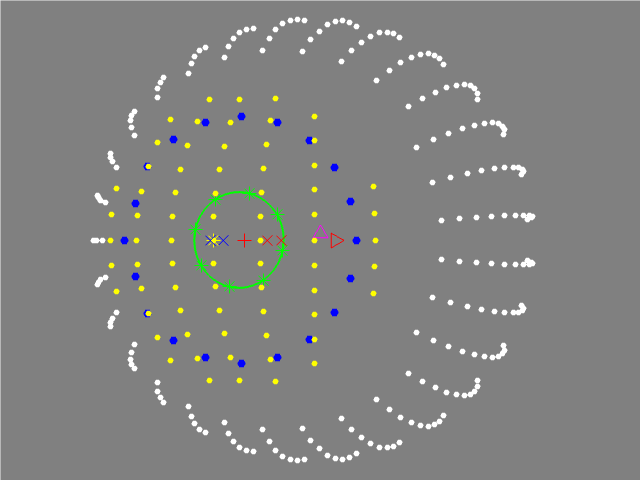

ans =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 360 320 240]
       Units: 'pixels'

  Show all properties


renderEyePose_lyy([-20,0,0,2],sg)

[~,glint_coord_lyy,~,~,~,~,point_labels_lyy]=projectModelEye_lyy(poses{1},sg,'fullEyeModelFlag',false)

glint_coord_lyy =   289.9899  255.0561
  303.4413  254.8703
  274.6857  280.6639
  265.1091  281.2854


point_labels_lyy = 16×1 cell array
    {'stopPerimeter' }
    {'stopPerimeter' }
    {'stopPerimeter' }
    {'stopPerimeter' }
    {'stopPerimeter' }
    {'stopPerimeter' }
    {'pupilPerimeter'}
    {'pupilPerimeter'}
    {'pupilPerimeter'}
    {'pupilPerimeter'}
    {'pupilPerimeter'}
    {'pupilPerimeter'}
    {'glint_01'      }
    {'glint_02'      }
    {'glint_4th_01'  }
    {'glint_4th_02'  }


## quantification

pupil_diam_quanti=2;
light_positions_quanti=[10,0,-110]';
sg_quanti=createSceneGeometry('cameraGlintSourceRelative',light_positions_quanti);

num_step=100;
pose_seq=zeros(num_step,4);
pose_seq(:,4)=2;
tmp=linspace(-15,15,num_step)';
pose_seq(:,1)=tmp;

glint_1st_quanti=[];
glint_4th_quanti=[];
for i=1:num_step
    % disp(i)
    [~,glint_coord_tmp,~,~,~,~,point_labels_quanti,~,~,~]=projectModelEye_lyy(pose_seq(i,:),sg_quanti,'fullEyeModelFlag',false);
    glint_1st_quanti(i,:)=glint_coord_tmp(1,:);
    glint_4th_quanti(i,:)=glint_coord_tmp(2,:);
end

vec_dpi=glint_4th_quanti-glint_1st_quanti;


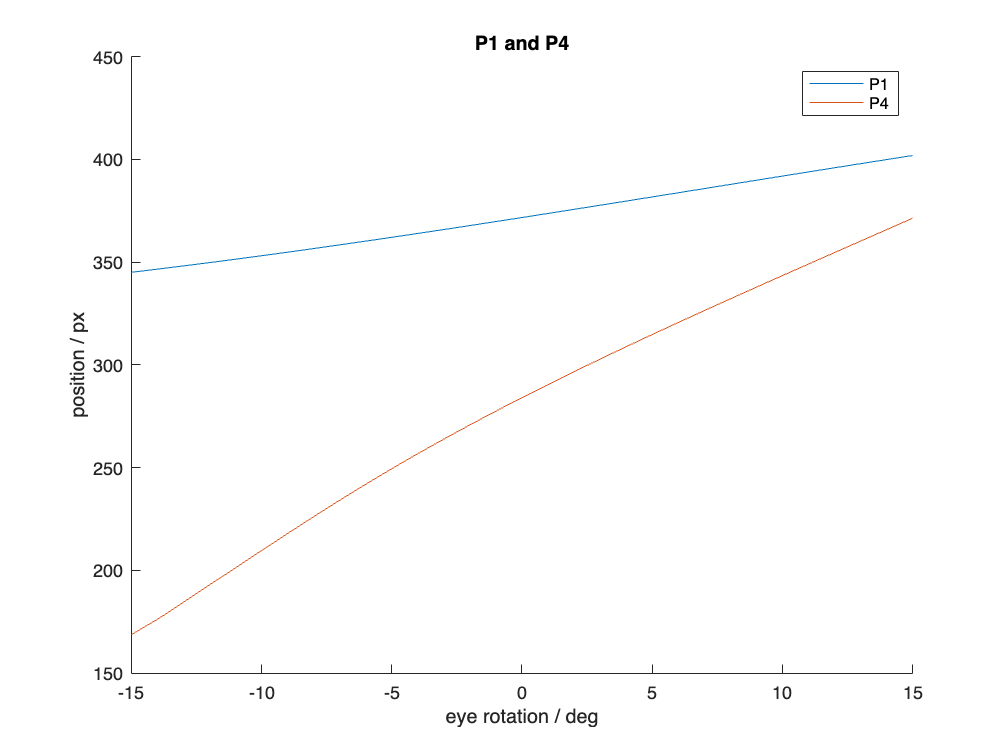

figure
hold on
plot(pose_seq(:,1),glint_1st_quanti(:,1))
plot(pose_seq(:,1),glint_4th_quanti(:,1))
legend('P1','P4')
xlabel('eye rotation / deg')
ylabel('position / px')
title('P1 and P4')
hold off

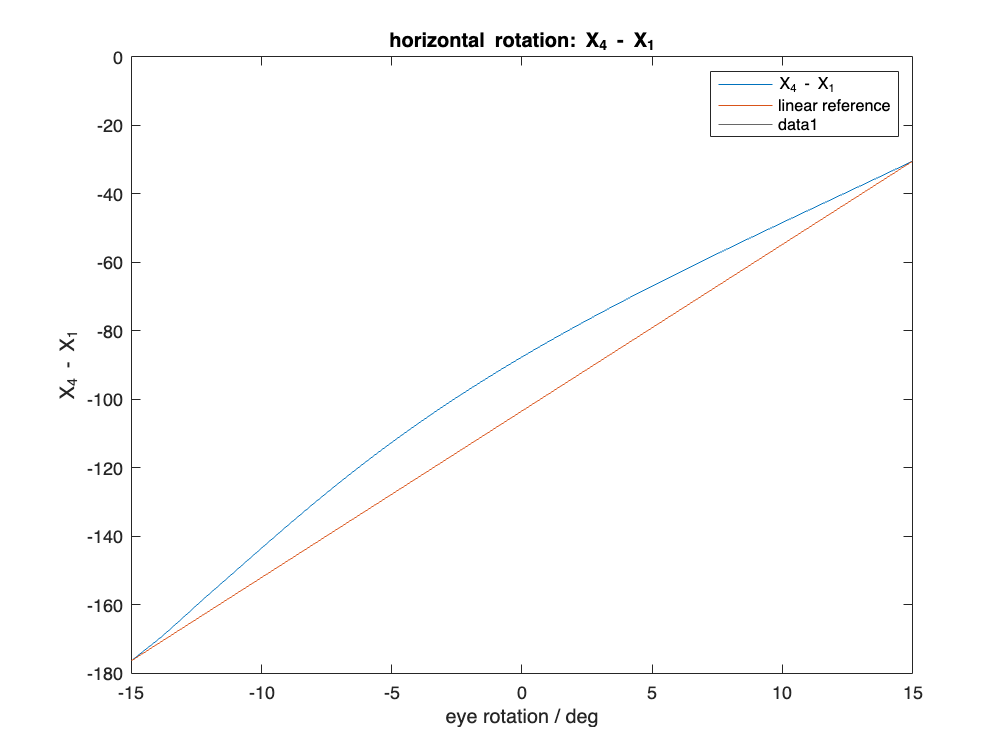

figure
plot(pose_seq(:,1),vec_dpi(:,1))
hold on
plot(pose_seq(:,1),linspace(vec_dpi(1,1),vec_dpi(end,1),size(pose_seq,1)))
title('horizontal rotation: X_{4} - X_{1}')
ylabel('X_{4} - X_{1}')
xlabel('eye rotation / deg')
legend('X_{4} - X_{1}','linear reference')
yline(0)
% xline(0)
hold off

% plot(pose_seq(:,1),vecnorm(vec_dpi(:,1),2,2))


% figure
% plot(pose_seq(:,1),vec_dpi(:,1))
hold on
% plot(pose_seq(:,1),linspace(vec_dpi(1,1),vec_dpi(end,1),size(pose_seq,1)))
title('horizontal rotation: X_{4} - X_{1}, varying light position along x axis')
ylabel('X_{4} - X_{1}')
xlabel('eye rotation / deg')
legend('0','10','-10','-20','20')

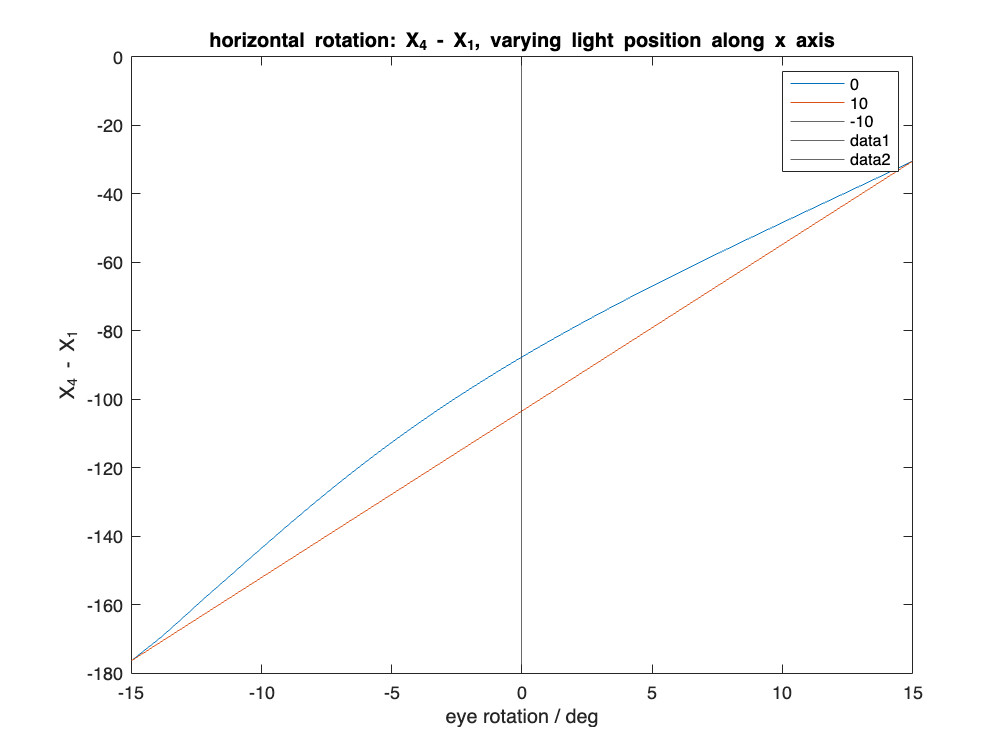

yline(0)
xline(0)

% hold off

pupilEllipseParams = 1.0e+03 *

    0.4034    0.2400    6.7887    0.0004    0.0016


imagePoints =   406.9477  199.1044
  377.6478  204.3846
  360.3009  230.6748
  365.2708  262.4991
  389.5760  280.9963
  418.7775  275.4087
  435.8404  249.2260
  430.9688  217.7091
  398.2725  240.0000
  398.2725  240.0000


pointLabels = 637×1 cell array
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopPerimeter'      }
    {'stopCenter'         }
    {'irisActualCenter'   }
    {'aziRotationCenter'  }
    {'eleRotationCenter'  }
    {'vertex'             }
    {'fovea'              }
    {'opticDisc'          }
    {'medialCanthus'      }
    {'lateralCanthus'     }
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}
    {'irisActualPerimeter'}


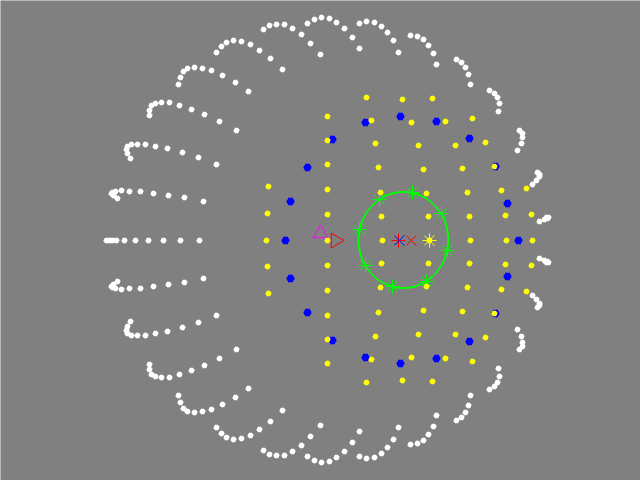

renderEyePose_lyy([20,0,0,2],sg_quanti);

sg_quanti.cameraPosition.translation(3,1)=50

sg_quanti = struct with fields:
    cameraIntrinsic: [1×1 struct]
     cameraPosition: [1×1 struct]
     screenPosition: [1×1 struct]
                eye: [1×1 struct]
         refraction: [1×1 struct]
               meta: [1×1 struct]


% sg_quanti.cameraPosition.glintSourceRelative=[50,0,100]'

### for fitting tool

x=pose_seq(:,1);
y=vec_dpi(:,1)

y =  -176.3654
 -174.5392
 -172.6838
 -170.9094
 -169.0012
 -166.9671
 -164.9092
 -162.8301
 -160.7329
 -158.6204


% curvefit

## plot the ray path

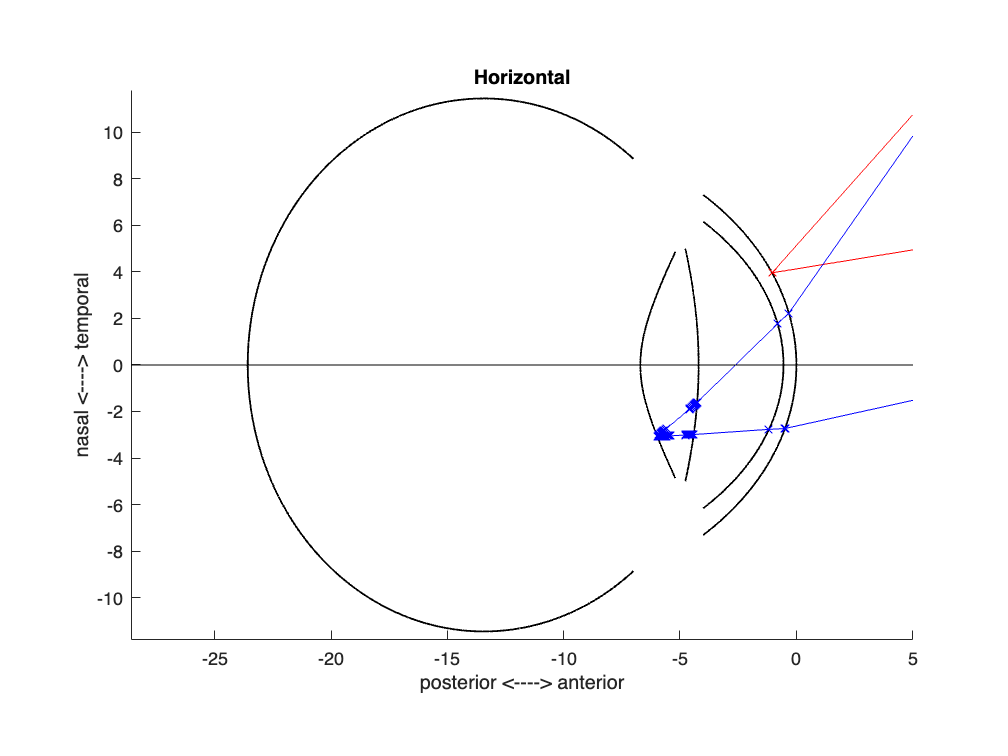

ans =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [476 360 560 420]
       Units: 'pixels'

  Show all properties


pose=[-10,0,0,2];

[~,glint_coord_tmp,~,~,~,~,~,~,~,initial_ray_1st,ray_path_1st,output_ray_1st,initial_ray_4th,ray_path_4th,output_ray_4th]=projectModelEye_lyy(pose,sg_quanti,'fullEyeModelFlag',false);

views={'horizontal','vertical'};

% ray_path_1st(end+1,:)=ray_path_1st(end,:)+output_ray_1st(2,:)*100;
% ray_path_4th(end+1,:)=ray_path_4th(end,:)+output_ray_4th(2,:)*100;
camera_in_eye_coord=convertWorldToEyeCoord(sg_quanti.cameraPosition.translation);
ray_path_1st(end+1,:)=rotateEyeCoord(camera_in_eye_coord,pose,sg_quanti.eye.rotationCenters,'inverse');
ray_path_4th(end+1,:)=rotateEyeCoord(camera_in_eye_coord,pose,sg_quanti.eye.rotationCenters,'inverse');



plotModelEyeSchematic_lyy(sg_quanti,'view',views{1},'rayPath_1st',ray_path_1st,'rayPath_4th',ray_path_4th)


% plotOpticalSystem_lyy(sg_quanti,'rayPath_1st',ray_path_1st','rayPath_4th',ray_path_4th','newFigure',true);
% addCameraIcon(sg_quanti,[-pose(1),pose(2)])

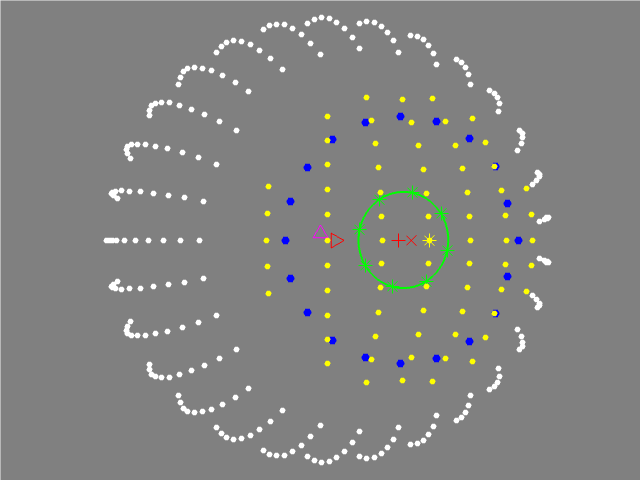

renderEyePose([20,0,0,2],sg_quanti);

## parallel source

% parallel_rays=get_mesh_parallel_rays([-1,0,0],[110,2,0],2,10);

% ray_direction_vec_non_norm=[-1,0,0];
% ray_center=[110,0,0];
% radius=6;

% ray_direction_vec_non_norm=[-0.8,-0.1,0];
% ray_center=[110,14,0];
% radius=6;

% ray_direction_vec_non_norm=[-0.8,-0.35,0];
% ray_center=[110,50,0];
% radius=6;

% ray_direction_vec_non_norm=[-0.8,-0.5,0];
% ray_center=[110,70,0];
% radius=6;

% ray_direction_vec_non_norm=[-0.8,-0.1,0];
% ray_center=[110,18,0];
% radius=1;

ray_direction_vec_non_norm=[-0.8,-0.35,0];
% ray_center=[110,51,0];
% ray_center=[110,50,0];
% ray_center=[110,49.5,0];
% ray_center=[110,48,0];
ray_center=[110,45,0];
radius=1;



% ray_direction_vec_non_norm=[-0.8,-0.5,0];
% ray_center=[110,70,0];
% radius=1;



ray_direction_vec=ray_direction_vec_non_norm/norm(ray_direction_vec_non_norm);
parallel_rays=get_mesh_parallel_rays(ray_direction_vec,ray_center,radius,20);


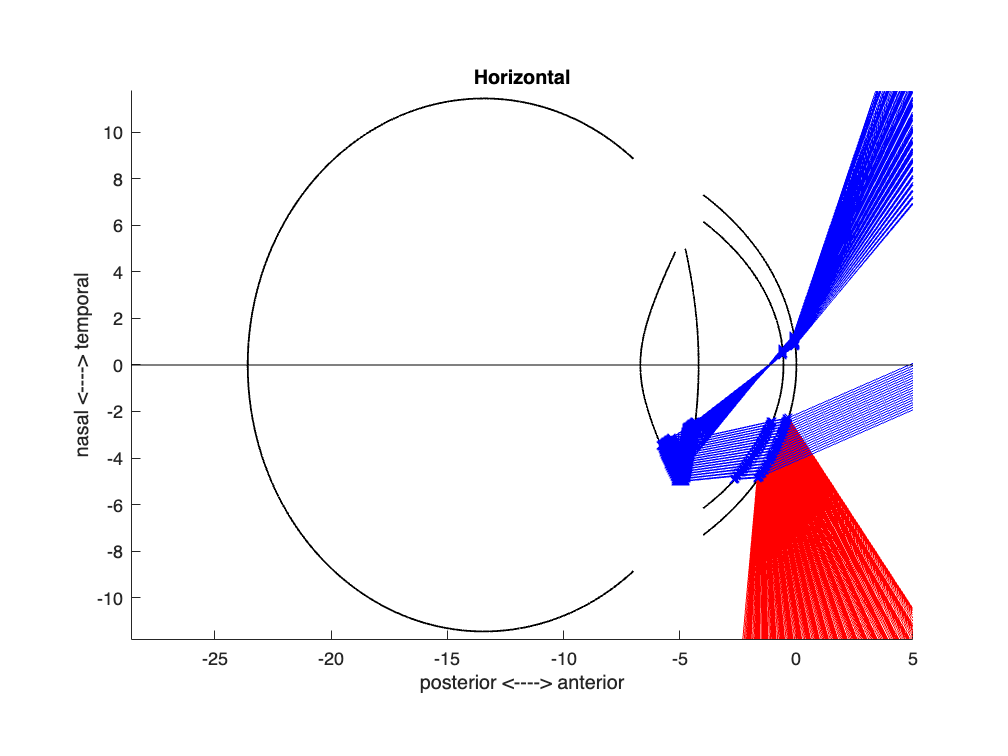

ans =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [1 1 1]
    Position: [476 360 560 420]
       Units: 'pixels'

  Show all properties


pose=[0,0,0,2];
% parallel_rays={[110,1,0;-1,0,0],[110,-1,0;-1,0,0]};

[~,~,~,~,~,~,~,~,~,ray_path_1st,ray_path_4th]=projectModelEye_lyy_parallel(pose,sg_quanti,'fullEyeModelFlag',false,'parallelRays',parallel_rays);


plotModelEyeSchematic_lyy(sg_quanti,'view',views{1},'rayPath_1st',ray_path_1st,'rayPath_4th',ray_path_4th)

% plotModelEyeSchematic_lyy(sg_quanti,'view',views{1},'rayPath_1st',ray_path_1st)
% plotModelEyeSchematic_lyy(sg_quanti,'view',views{1},'rayPath_4th',ray_path_4th)

% plotOpticalSystem_lyy(sg_quanti,'rayPath_1st',ray_path_1st','rayPath_4th',ray_path_4th','newFigure',true);
% plotOpticalSystem_lyy(sg_quanti,'rayPath_1st',ray_path_1st','newFigure',true);
% plotOpticalSystem_lyy(sg_quanti,'rayPath_4th',ray_path_4th','newFigure',true);